## **数据处理**

**注释：**

- **Minflux 原始数据如果是 Json 格式则运行 一，提取Json 提取有效信息**

- **Minflux 原始数据如果是 Npy 格式，则需要先运行 Python 程序 MinfluxNpyToMat再运行 二，提取Mat 提取有效信息**

### **一，提取Json**数据

close all;clear;clc;

path1 = '/Users/GluA1 680 GluA2 Cy5 M3 raw';
data1 = readcell(path1);
flag1 = false;
flag2 = 'true';
flag3 = false;
name1 = 'itr: 9';
name2 = 'itr: 4';
num = size(data1, 1);

for i = 1 : num
    if strcmp(name1, data1{i, 1})
        flag1 = true;
        break
    end
end

if flag1
    k = 0;
    for i = 1 : num
        if strcmp(name1, data1{i, 1}) && strcmp(flag2, data1{i+32, 1}(1, 6:end))
            if min(~isnan([data1{i+3, 1}, data1{i+4, 1}, data1{i+5, 1}]))
                k = k + 1;
                tic(k, 1) = str2num(data1{i+1, 1}(1, 5:end));
                loc(k, 1) = data1{i+3, 1};
                loc(k, 2) = data1{i+4, 1};
                loc(k, 3) = data1{i+5, 1};
                efo(k, 1) = str2num(data1{i+9, 1}(1, 5:end));
                cfr(k, 1) = str2num(data1{i+12, 1}(1, 5:end));
                dcr(k, 1) = str2num(data1{i+13, 1}(1, 5:end));
            end
        end
    end
else
    k = 0;
    for i = 1 : num
        if strcmp(name2, data1{i, 1}) && strcmp(flag2, data1{i+32, 1}(1, 6:end))
            if min(~isnan([data1{i+3, 1}, data1{i+4, 1}]))
                k = k + 1;
                tic(k, 1) = str2num(data1{i+1, 1}(1, 5:end));
                loc(k, 1) = data1{i+3, 1};
                loc(k, 2) = data1{i+4, 1};
                efo(k, 1) = str2num(data1{i+9, 1}(1, 5:end));
                cfr(k, 1) = str2num(data1{i+12, 1}(1, 5:end));
                dcr(k, 1) = str2num(data1{i+13, 1}(1, 5:end));
            end
        end
    end
end

### 二，提取Mat数据

close all;clear;clc;
flag1 = false;
flag2 = 'true';
flag3 = false;
path2 = '/Users/WangHao/Desktop/1003/Alex 647 alpha-tublin M9.msr.npy.mat';
data2 = load(path2);
loc = data2.loc;
tid = data2.tid;

## 数据可视化

**注释：**

- **一，Loc点云 根据loc信息画出散点图**

- **二，Dcr点云 根据loc信息画出散点图，并根据Dcr信息对点云着色**

- **三，Efo点云 根据loc信息画出散点图，并根据Efo信息对点云着色**

- **四，DBSCAN 对loc信息进行聚类分析，并根据簇信息对点云着色**

- **五，离散拟合 先选取ROI区域，对区域内数据进行球或圆拟合分析**

### 一，Loc点云

   1.0e-05 *

   -0.3647    0.3614
   -0.3699    0.3748
   -0.0354    0.0645



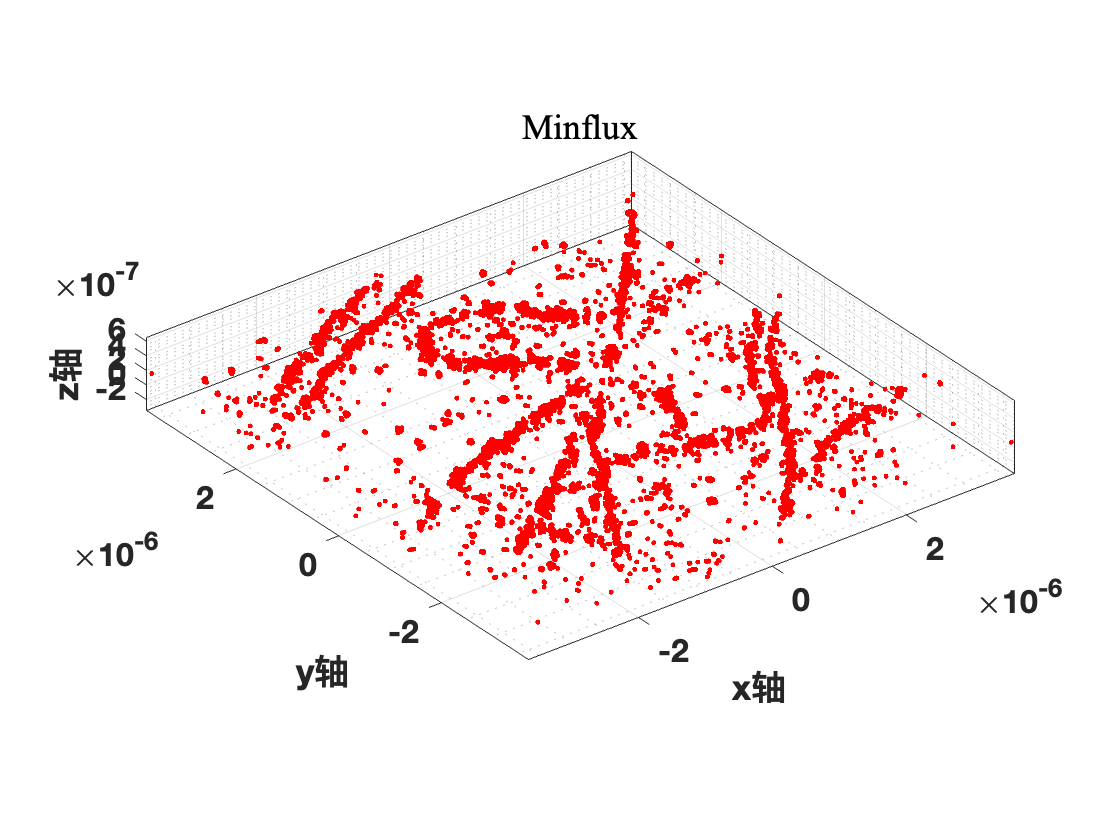

if size(loc, 2) == 3
    result_max = max(loc, [], 1);
    x_max = result_max(1, 1);
    y_max = result_max(1, 2);
    z_max = result_max(1, 3);
    
    result_min = min(loc, [], 1);
    x_min = result_min(1, 1);
    y_min = result_min(1, 2);
    z_min = result_min(1, 3);
    
    disp([x_min, x_max; y_min, y_max; z_min, z_max])
    
    X = loc(:, 1);
    Y = loc(:, 2);
    Z = loc(:, 3);
    
    scatter3(X, Y, Z, 'r.');
    axis equal
    box on;
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'zgrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    set(gca, 'zminorgrid', 'on');
    title('Minflux', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
else
    result_max = max(loc, [], 1);
    x_max = result_max(1, 1);
    y_max = result_max(1, 2);
    
    result_min = min(loc, [], 1);
    x_min = result_min(1, 1);
    y_min = result_min(1, 2);
    
    disp([x_min, x_max; y_min, y_max])
    
    X = loc(:, 1);
    Y = loc(:, 2);
    
    scatter(X, Y, 'b.');
    axis equal
    box on;
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    title('Minflux', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
end

### 二，Dcr点云

**1，Drc**直方拟合

dcr = dcr_nonoise;
histogram(dcr, 100, 'Normalization', 'pdf');

hold on;
[pdf_kernel, pdf_evalpts, bw] = ksdensity(dcr, 'Bandwidth', 0.018);
plot(pdf_evalpts, pdf_kernel, 'r', 'LineWidth', 1.5);
evalpts_min = pdf_evalpts(islocalmin(pdf_kernel));
kernel_min = pdf_kernel(islocalmin(pdf_kernel));
if ~isempty(evalpts_min)
    for i = 1 : length(evalpts_min)
        plot([evalpts_min(i), evalpts_min(i)], [0, kernel_min(i)], 'r', 'LineWidth', 1.5);
        text(evalpts_min(i), kernel_min(i), strcat('(', num2str(evalpts_min(i)),' ', num2str(kernel_min(i)), ')'));
    end
end

evalpts_max = pdf_evalpts(islocalmax(pdf_kernel));
kernel_max = pdf_kernel(islocalmax(pdf_kernel));

if ~isempty(evalpts_max)
    for i = 1 : length(evalpts_max)
        plot([evalpts_max(i), evalpts_max(i)], [0, kernel_max(i)], 'r', 'LineWidth', 1.5);
        text(evalpts_max(i), kernel_max(i), strcat('(', num2str(evalpts_max(i)),', ', num2str(kernel_max(i)), ')'));
    end
end
xlabel('dcr大小')
ylabel('dcr频率')
title('Dcr直方拟合')
set(gca, 'FontSize', 16, 'FontWeight', 'bold');
hold off;

disp([evalpts_min; kernel_min])

    0.2224    0.5872
    0.0017    1.9649



disp([evalpts_max; kernel_max])

    0.1976    0.4794    0.7033
    0.0025    2.7132    2.8217



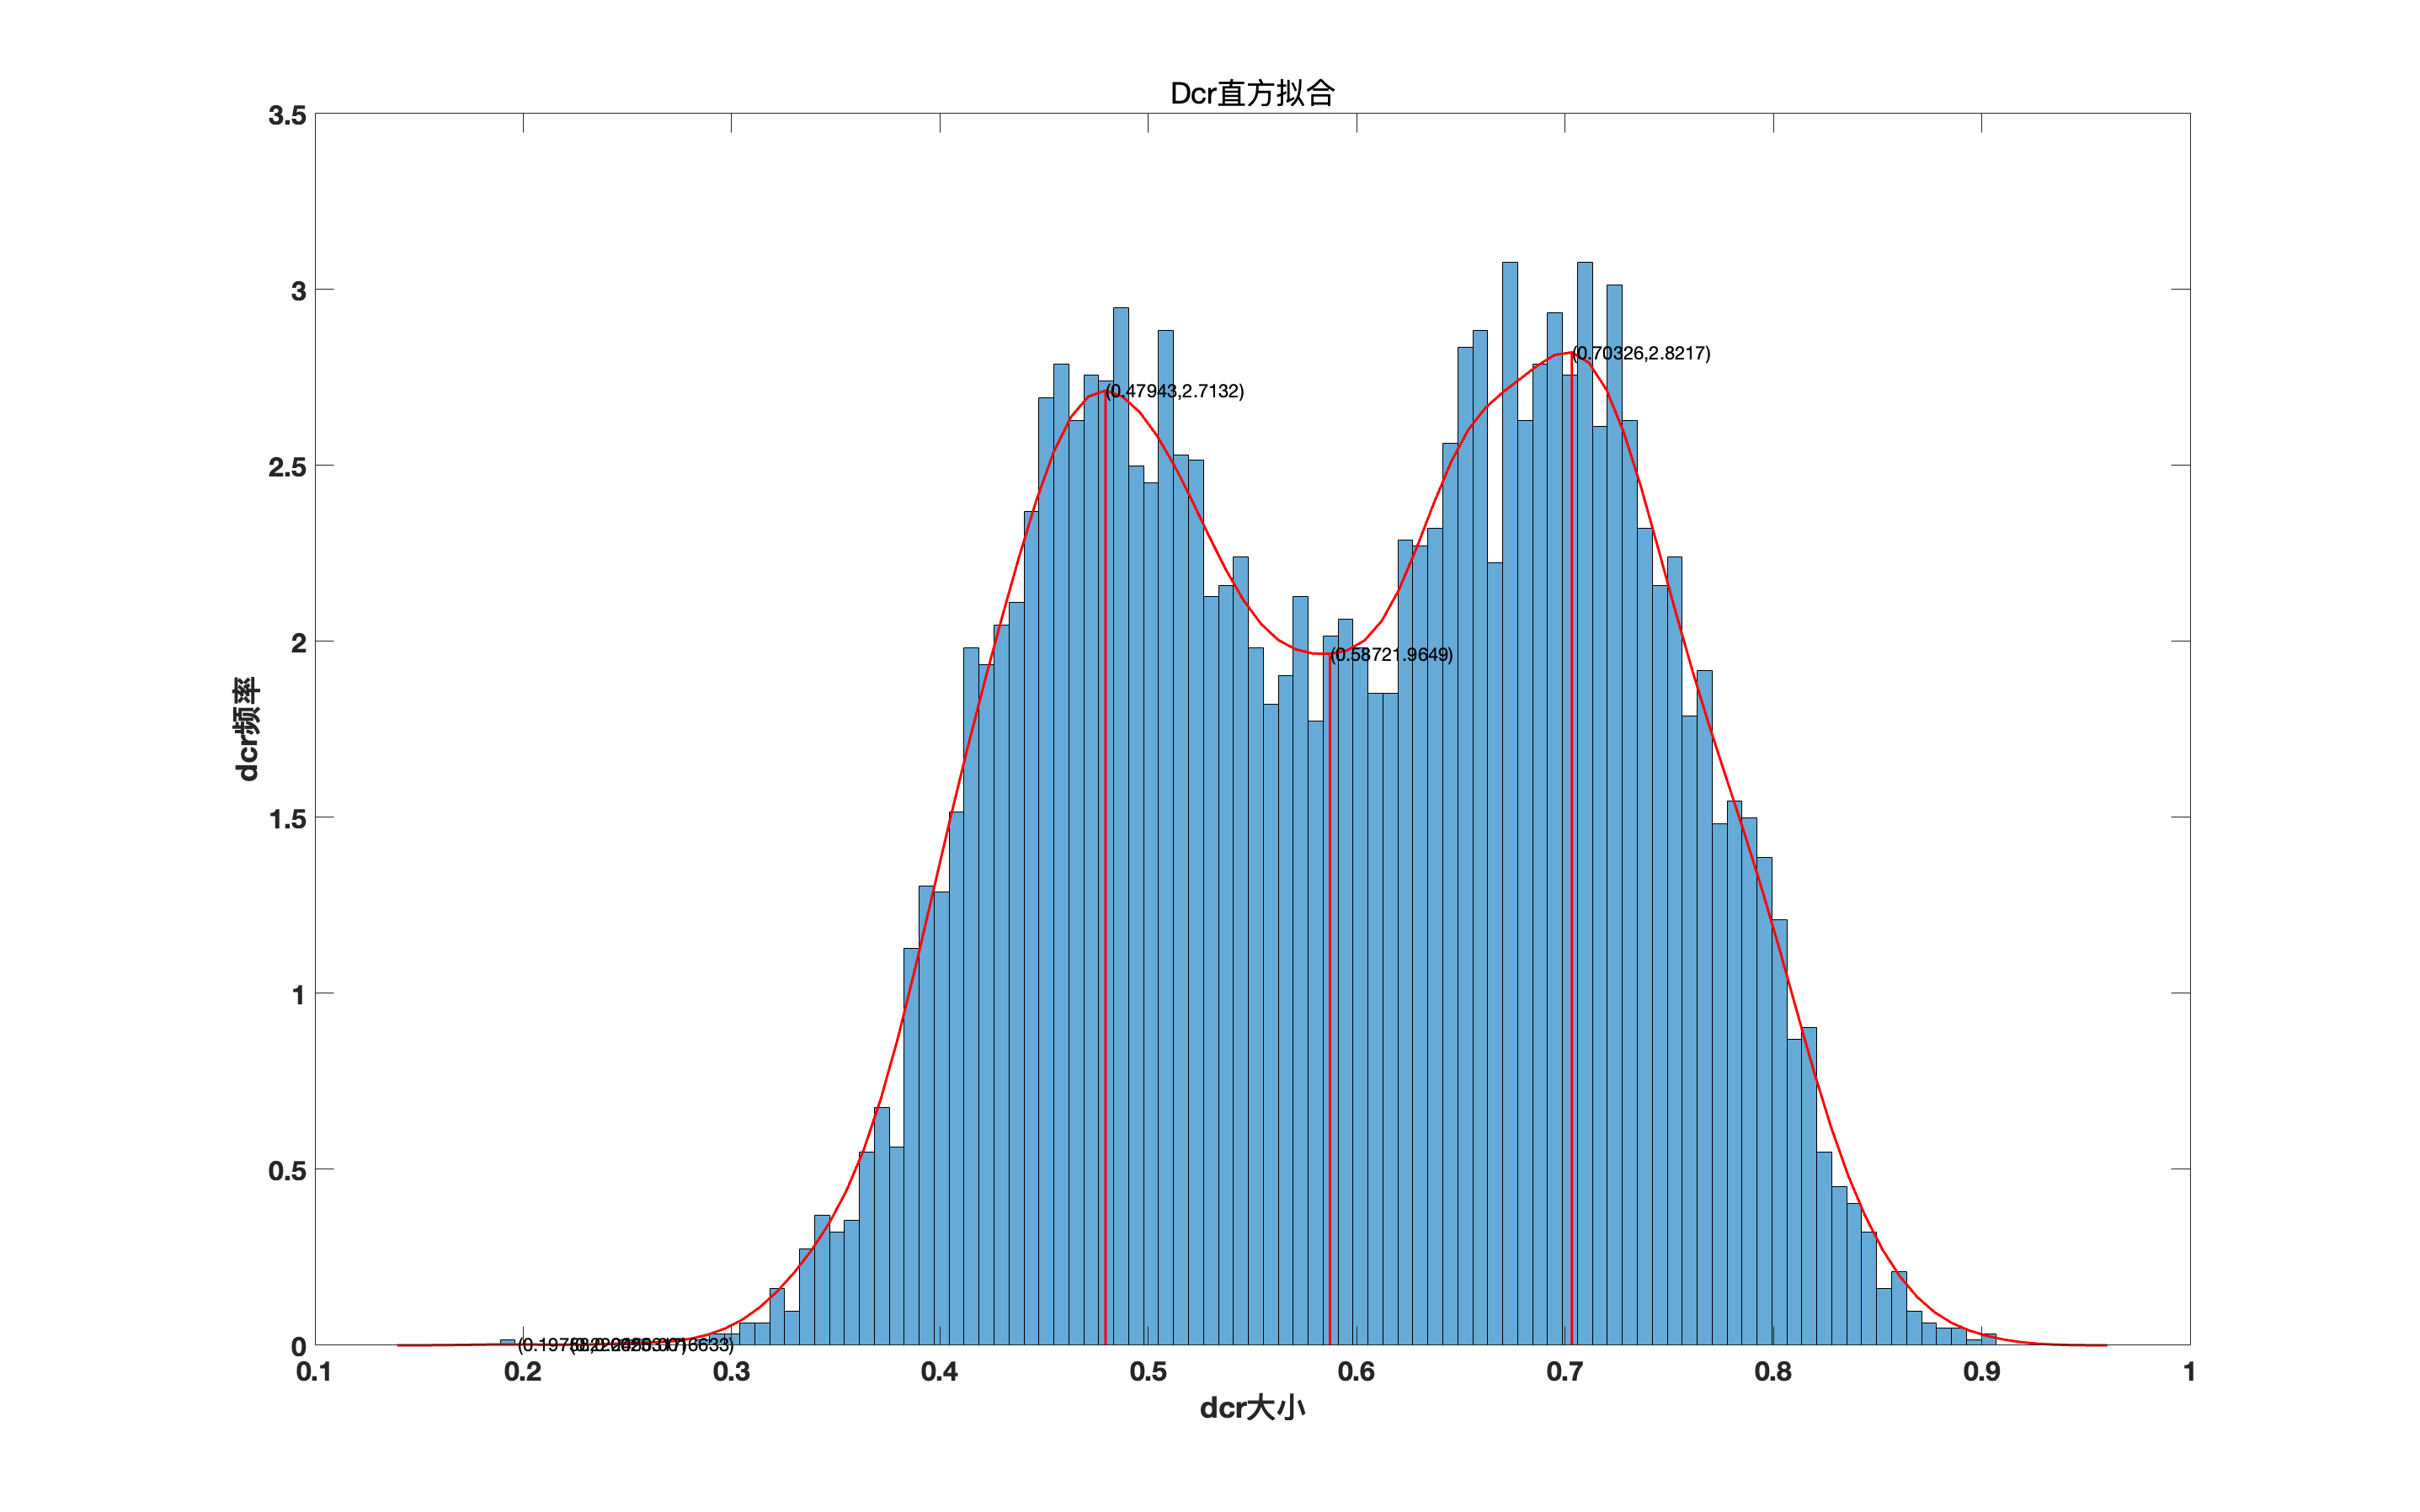


scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);

print(gcf, '/Volumes/NO NAME/Min PPT meterials/Yundou/dcr_nonoise直方拟合', '-dpng', '-r300');

**2，Drc三视图**

threshold = evalpts_min(find(kernel_min == min(kernel_min)));

if flag3 == true
    loc = loc_aim;
    dcr = dcr_aim;
end
loc = loc_nonoise;
i = find(dcr >= threshold);
loc1 = loc(i, :);
j = find(dcr < threshold);
loc2 = loc(j, :);

if size(loc, 2) == 3
    scatter3(loc1(:, 1), loc1(:, 2), loc1(:, 3), 16, 'red', 'filled');
    hold on;
    scatter3(loc2(:, 1), loc2(:, 2), loc2(:, 3), 16, 'blue', 'filled');
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'zgrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    set(gca, 'zminorgrid', 'on');
    title('MinfluxDcr', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    hold off;
elseif size(loc, 2) == 2
    scatter(loc1(:, 1), loc1(:, 2), 'r.');
    hold on;
    scatter(loc2(:, 1), loc2(:, 2), 'b.');
    xlabel('x轴')
    ylabel('y轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    title('MinfluxDcr', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    hold off;
end

if ~isempty(loc1) && ~isempty(loc2)
    l1 = floor(256*threshold);
    l2 = floor(256*(1-threshold));
    bar1 = [linspace(1,1,l2)', linspace(0,0,l2)', linspace(0,0,l2)'];
    bar2 = [linspace(0,0,l1)', linspace(0,0,l1)', linspace(1,1,l1)'];
    colormap(cat(1, bar1, bar2))
else
    colormap([1, 0, 0])
end

view([1, 1, 1])
axis equal
colorbar('Ticks',[0, threshold, 1]);
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Volumes/NO NAME/Min PPT meterials/Yundou/dcr', '-dpng', '-r300');

view([0, 0, 1])
axis equal
colorbar('Ticks',[0, threshold, 1]);
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Volumes/NO NAME/Min PPT meterials/Yundou/dcr_z', '-dpng', '-r300');

view([0, 1, 0])
axis equal
colorbar('Ticks',[0, threshold, 1]);
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Volumes/NO NAME/Min PPT meterials/Yundou/dcr_y', '-dpng', '-r300');

view([1, 0, 0])
axis equal
colorbar('Ticks',[0, threshold, 1]);
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Volumes/NO NAME/Min PPT meterials/Yundou/dcr_x', '-dpng', '-r300');

### 三，Efo点云

**1，Efo直方拟合**

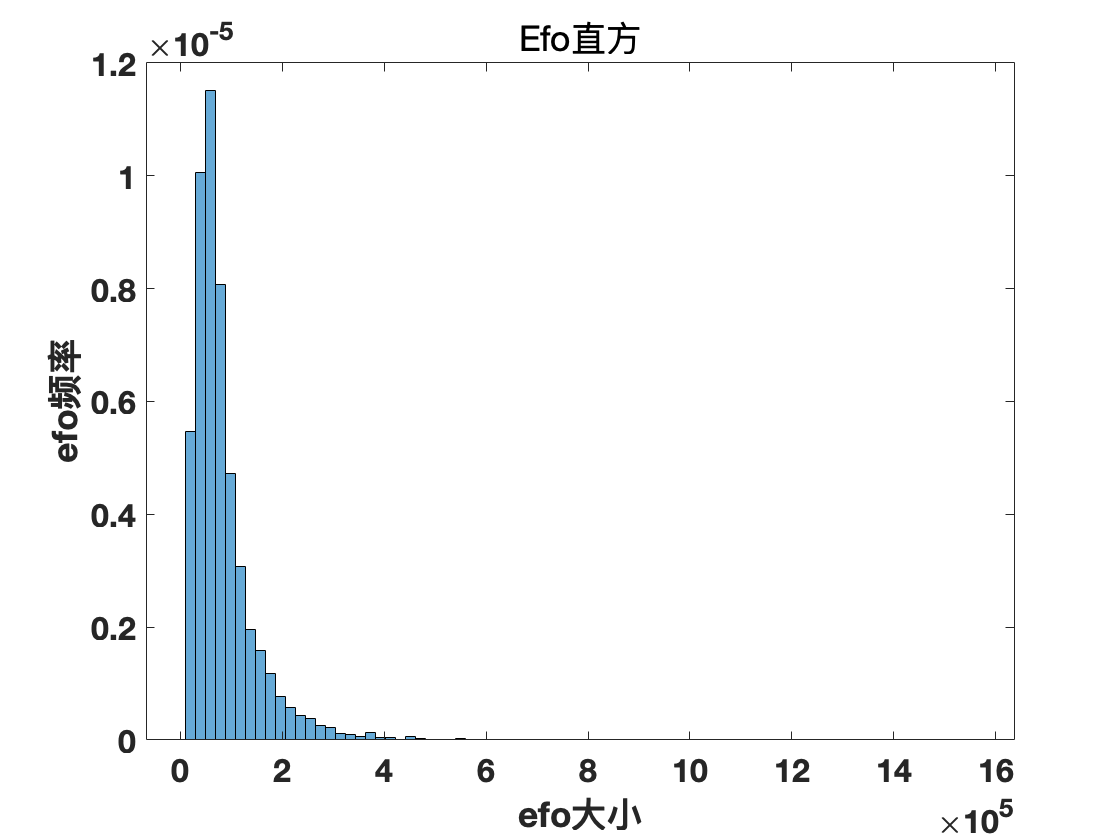

histogram(efo, round(sqrt(length(dcr))), 'Normalization', 'pdf');
xlabel('efo大小')
ylabel('efo频率')
title('Efo直方')
set(gca, 'FontSize', 16, 'FontWeight', 'bold');

**2，Efo三视图**

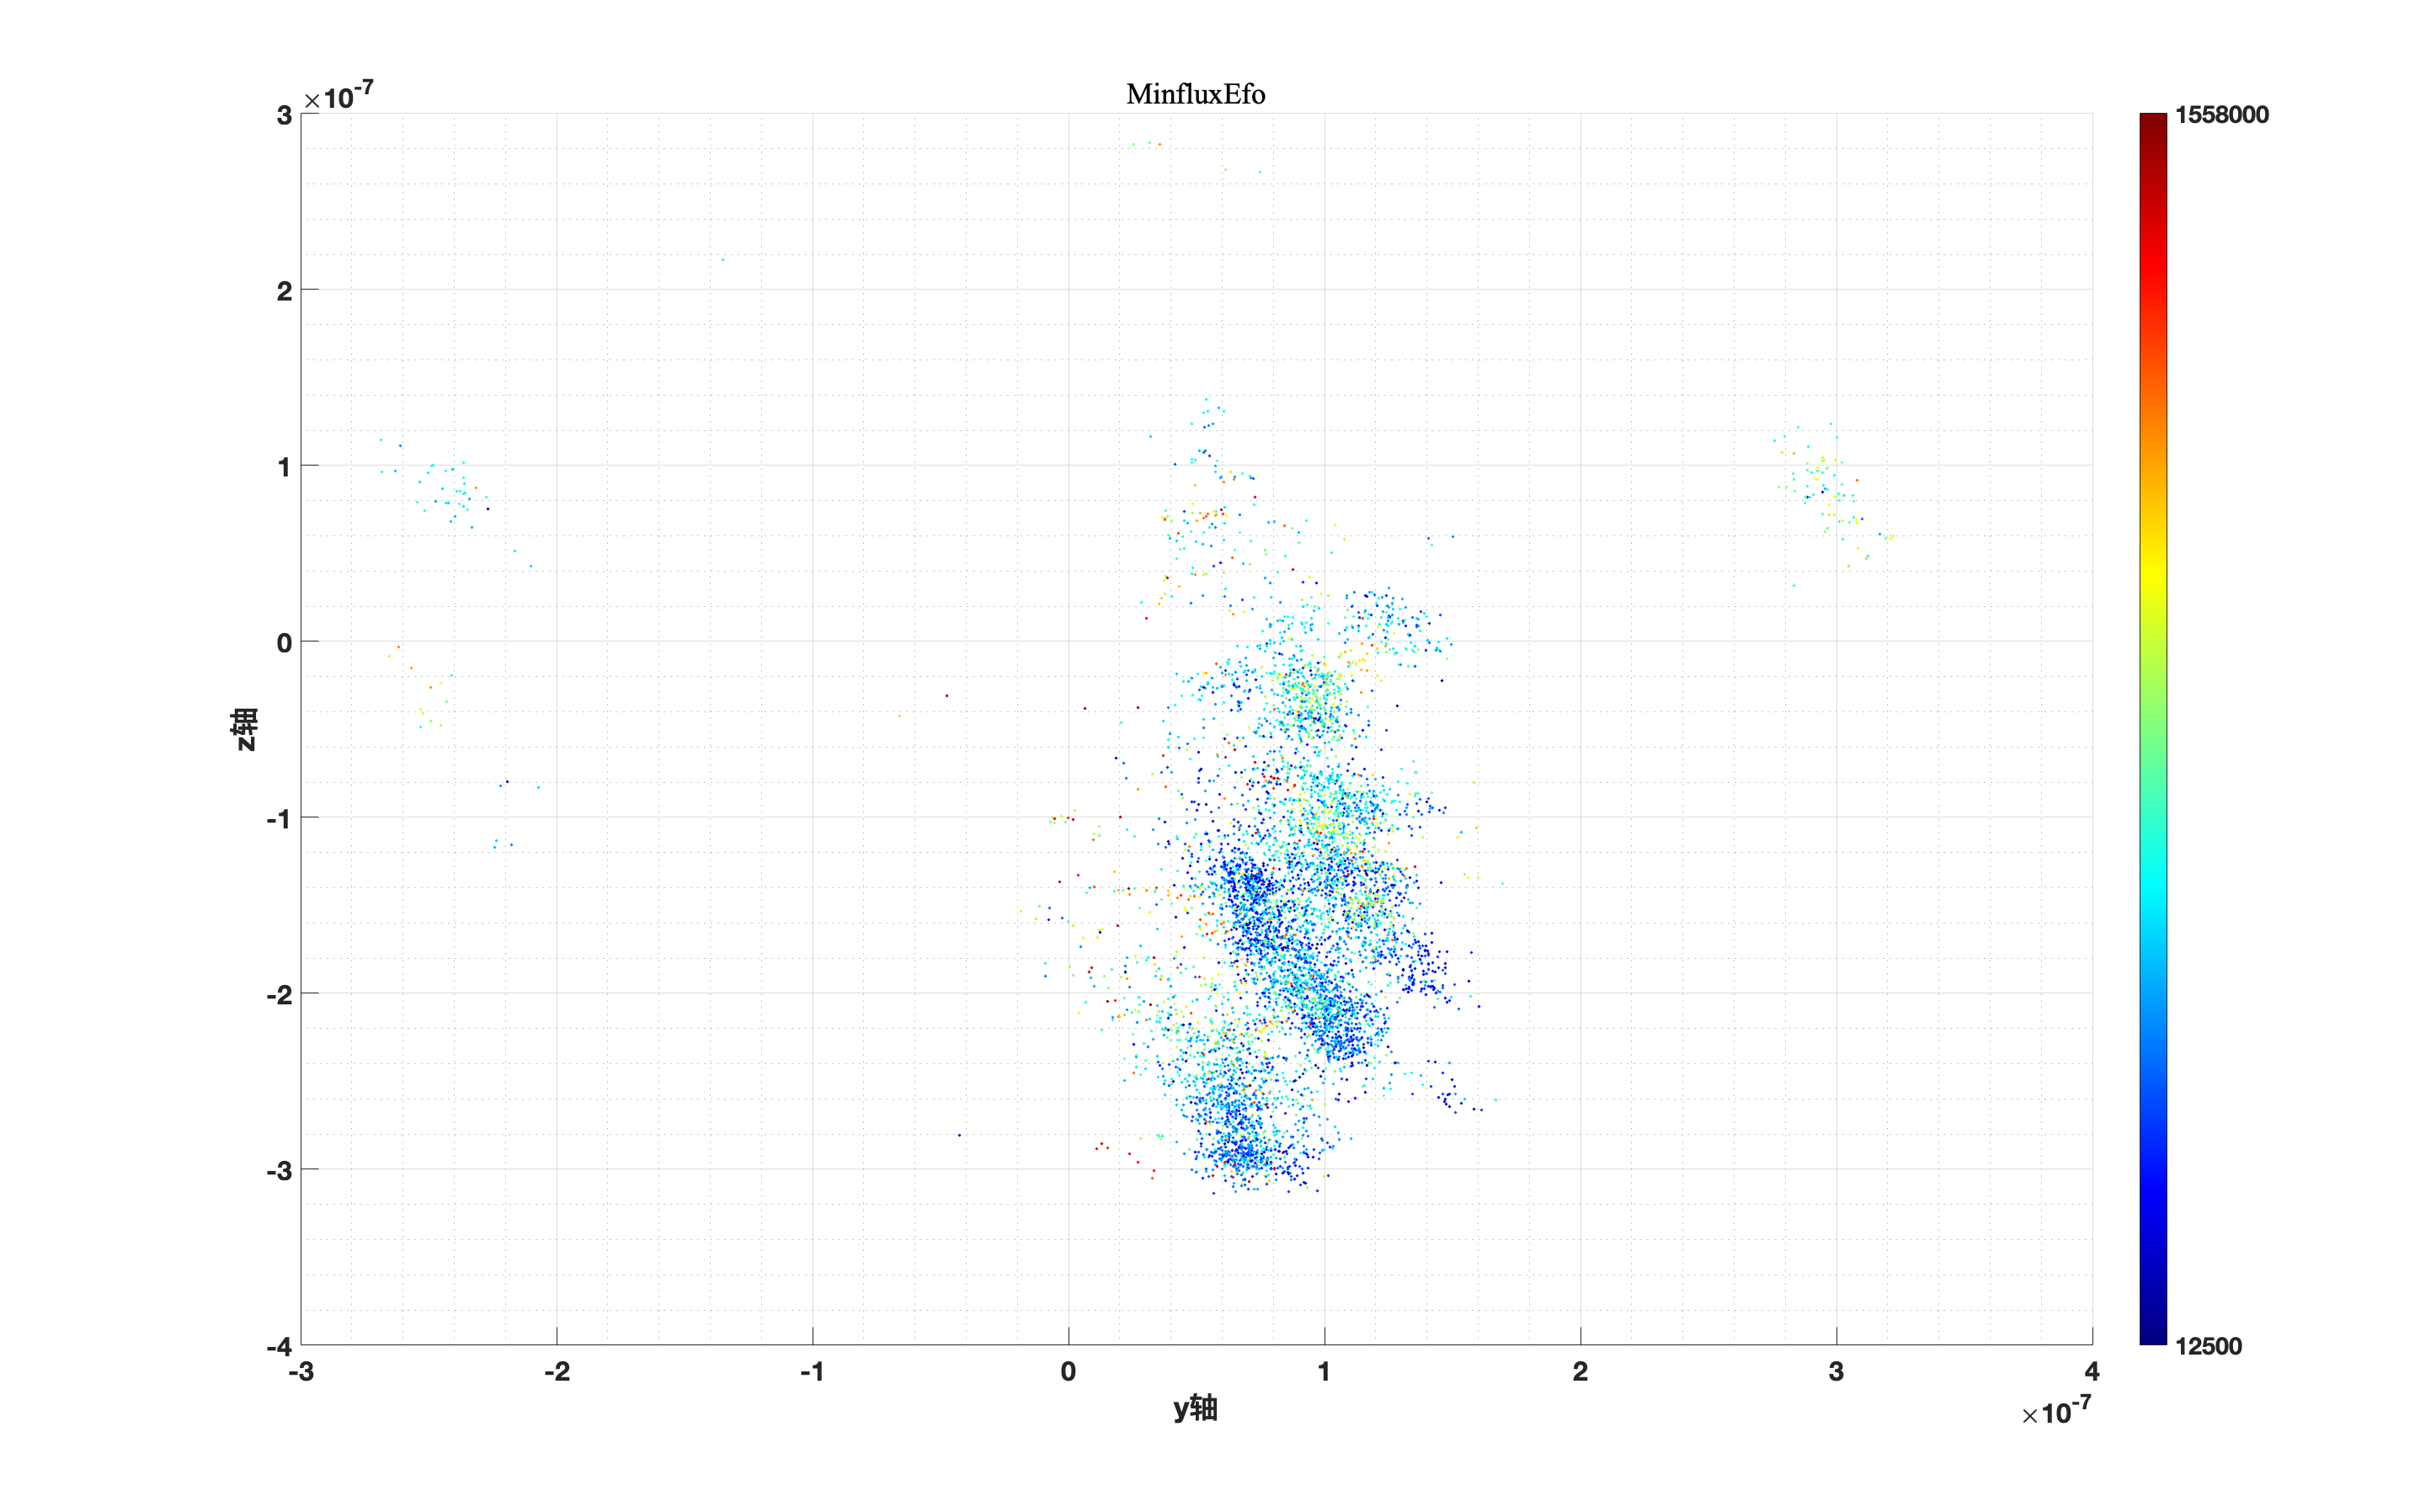

if flag3 == true
    loc = loc_aim;
    efo = efo_aim;
end

uq_efo = unique(efo);
l = length(uq_efo)/8+1;
map1 = [linspace(0,0,l)', linspace(0,0,l)', linspace(0.5,1,l)'];
map2 = [linspace(0,0,2*l)', linspace(0,1,2*l)', linspace(1,1,2*l)'];
map3 = [linspace(0,1,2*l)', linspace(1,1,2*l)', linspace(1,0,2*l)'];
map4 = [linspace(1,1,2*l)', linspace(1,0,2*l)', linspace(0,0,2*l)'];
map5 = [linspace(1,0.5,l)', linspace(0,0,l)', linspace(0,0,l)'];
cmap = cat(1, map1, map2, map3, map4, map5);

if size(loc, 2) == 3
    for i = 1 : length(efo)
        x(i, 1) = find(uq_efo == efo(i));
    end
    scatter3(loc(:, 1), loc(:, 2), loc(:, 3), 5, cmap(x, :), 'filled');
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'zgrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    set(gca, 'zminorgrid', 'on');
    title('MinfluxEfo', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
elseif size(loc, 2) == 2
    for i = 1 : length(efo)
        x(i) = find(uq_efo == efo(i));
    end
    scatter(loc(:, 1), loc(:, 2), 5, cmap(x, :), 'filled');
    xlabel('x轴')
    ylabel('y轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    title('MinfluxEfo', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
end

colormap(cmap)

view([1, 1, 1])
colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(efo)), num2str(max(efo))});
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Volumes/NO NAME/Min PPT meterials/Jing 0730/efo', '-dpng', '-r300');

view([0, 0, 1])
colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(efo)), num2str(max(efo))});
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Volumes/NO NAME/Min PPT meterials/Jing 0730/efo_z', '-dpng', '-r300');

view([0, 1, 0])
colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(efo)), num2str(max(efo))});
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Volumes/NO NAME/Min PPT meterials/Jing 0730/efo_y', '-dpng', '-r300');

view([1, 0, 0])
colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(efo)), num2str(max(efo))});
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Volumes/NO NAME/Min PPT meterials/Jing 0730/efo_x', '-dpng', '-r300');

### 四，Tim点云

**1，Tim直方拟合**

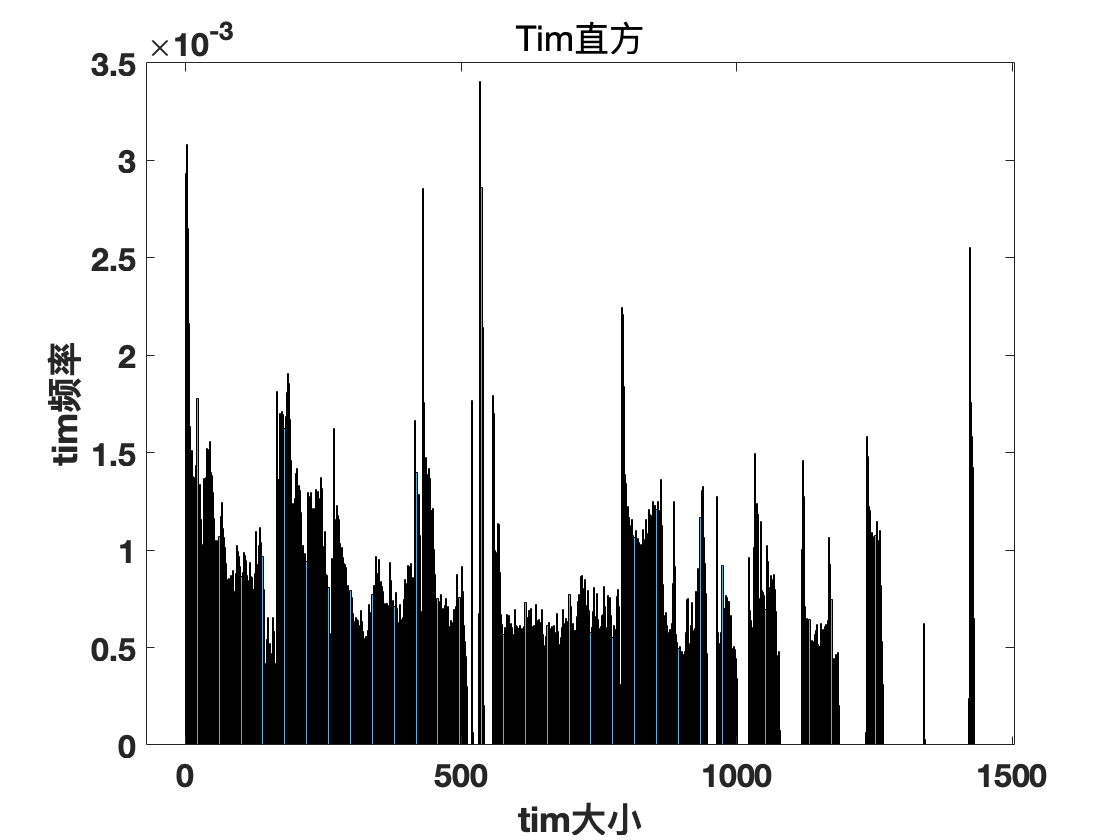

tim = tim(:, 2);
histogram(tim, round(sqrt(length(dcr))), 'Normalization', 'pdf');
xlabel('tim大小')
ylabel('tim频率')
title('Tim直方')
set(gca, 'FontSize', 16, 'FontWeight', 'bold');

**2，Tim三视图**

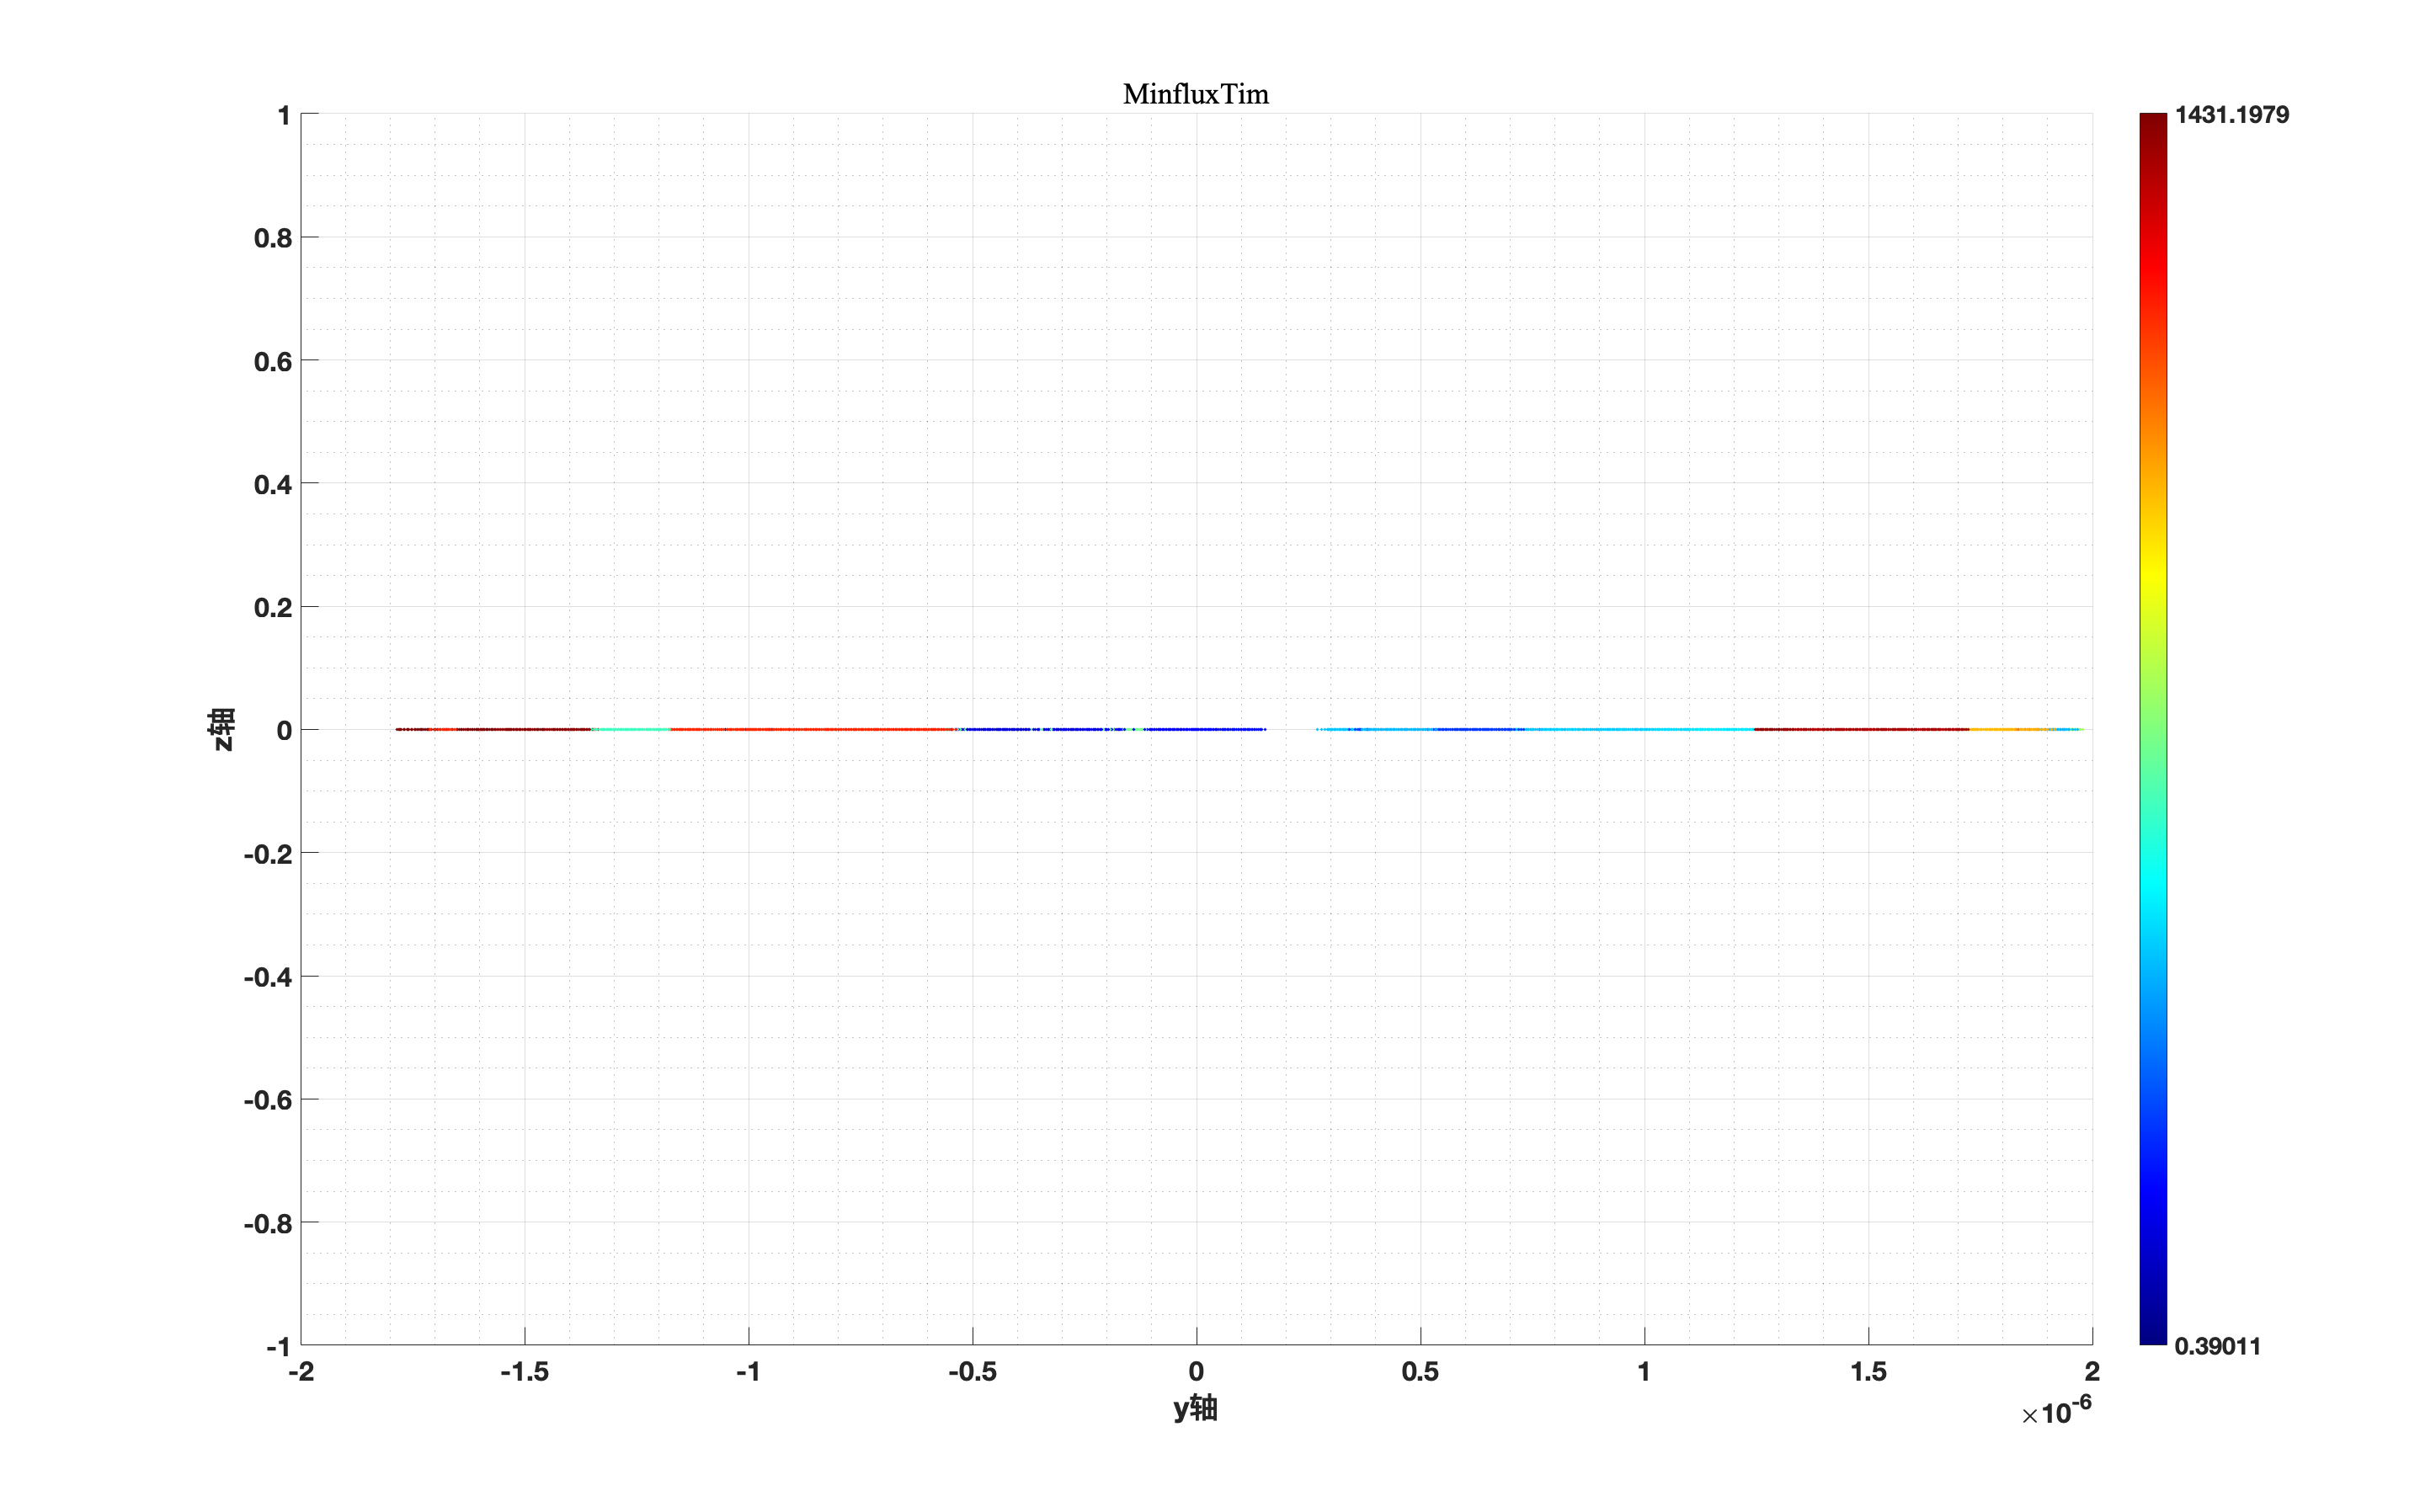

if flag3 == true
    loc = loc_aim;
    tim = tim_aim;
end

uq_tim = unique(tim);
l = length(uq_tim)/8+1;
map1 = [linspace(0,0,l)', linspace(0,0,l)', linspace(0.5,1,l)'];
map2 = [linspace(0,0,2*l)', linspace(0,1,2*l)', linspace(1,1,2*l)'];
map3 = [linspace(0,1,2*l)', linspace(1,1,2*l)', linspace(1,0,2*l)'];
map4 = [linspace(1,1,2*l)', linspace(1,0,2*l)', linspace(0,0,2*l)'];
map5 = [linspace(1,0.5,l)', linspace(0,0,l)', linspace(0,0,l)'];
cmap = cat(1, map1, map2, map3, map4, map5);

if size(loc, 2) == 3
    for i = 1 : length(tim)
        x(i, 1) = find(uq_tim == tim(i));
    end
    scatter3(loc(:, 1), loc(:, 2), loc(:, 3), 5, cmap(x, :), 'filled');
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'zgrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    set(gca, 'zminorgrid', 'on');
    title('MinfluxTim', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
elseif size(loc, 2) == 2
    for i = 1 : length(tim)
        x(i) = find(uq_tim == tim(i));
    end
    scatter(loc(:, 1), loc(:, 2), 5, cmap(x, :), 'filled');
    xlabel('x轴')
    ylabel('y轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    title('MinfluxTim', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
end

colormap(cmap)

view([1, 1, 1])
colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(tim)), num2str(max(tim))});
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Users/WangHao/Desktop/tim', '-dpng', '-r300');

view([0, 0, 1])
colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(tim)), num2str(max(tim))});
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Users/WangHao/Desktop/tim_z', '-dpng', '-r300');

view([0, 1, 0])
colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(tim)), num2str(max(tim))});
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Users/WangHao/Desktop/tim_y', '-dpng', '-r300');

view([1, 0, 0])
colorbar('Ticks',[0, 1], 'TickLabels',{num2str(min(tim)), num2str(max(tim))});

scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
print(gcf, '/Users/WangHao/Desktop/tim_x', '-dpng', '-r300');

### 四，DBSCAN

eps = 5e-8;
minpts = 50;
cluster = GetCluster(loc, eps, minpts);
area = 5;
noise = false;
ScatterCluster(loc, cluster, area, noise);

k = 1;
for i = 1 : length(cluster)
    if i ~= length(cluster)
        for j = 1 : length(cluster{i})
            loc_nonoise(k, 1:3) = loc(cluster{i}(j), :);
            dcr_nonoise(k) = dcr(cluster{i}(j));
            efo_nonoise(k) = efo(cluster{i}(j));
            k = k + 1;
        end
    end
end

### 五，离散拟合

#### 一，选取ROI数据

**1，游标选中目标**

loc_reg = cursor_info.Position;
for i = 1 : size(cluster, 2)
    ClusterP = cluster{i};
    if size(loc, 2) == 3
        for j = ClusterP
            if isequal(loc_reg, [loc(j, 1), loc(j, 2), loc(j, 3)])
                k = ClusterP';
                f = scatter3(loc(k, 1), loc(k, 2), loc(k, 3), 5, [0, 0, 1], 'filled');
                cs_aim = [loc(k, 1), loc(k, 2), loc(k, 3)];
            end
        end
    elseif size(loc, 2) == 2
        for j = ClusterP
            if isequal(loc_reg, [loc(j, 1), loc(j, 2)])
                k = ClusterP';
                f = scatter(loc(k, 1), loc(k, 2), 5, [0, 0, 1], 'filled');
                cs_aim = [loc(k, 1), loc(k, 2)];
            end
        end
    end
end
axis equal;
title('Minflux', 'FontName', 'Times New Roman');
xlabel('x轴')
ylabel('y轴')
zlabel('z轴')
legend(f, '目标点');

**2，滑窗选中区域**

rect = getrect(gcf);
x1 = rect(1);
x2 = x1+rect(3);
y1 = rect(2);
y2 = y1+rect(4);
aim = find(loc(:,1)>x1 & loc(:,1)<x2 & loc(:,2)>y1 & loc(:,2)<y2);
if size(loc, 2) == 3
    scatter3((loc(aim,1)), (loc(aim,2)), loc(aim,3), 5, [0, 0, 1], 'filled');
    z1 = min(loc(aim,3), [], 'all');
    z2 = max(loc(aim,3), [], 'all');
    axis([x1, x2, y1, y2, z1, z2]);
    xlabel('x轴');
    ylabel('y轴');
    zlabel('z轴');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    loc_aim = [loc(aim,1), loc(aim,2), loc(aim,3)];
    dcr_aim = dcr(aim);
    efo_aim = efo(aim);
elseif size(loc, 2) == 2
    scatter((loc(aim,1)), (loc(aim,2)), 5, [0, 0, 1], 'filled');
    axis([x1, x2, y1, y2]);
    xlabel('x轴');
    ylabel('y轴');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    loc_aim = [loc(aim,1), loc(aim,2)];
    dcr_aim = dcr(aim);
    efo_aim = efo(aim);
end

#### 二，数据球拟合

data1 = cs_aim;
f = @(p, data) (data(:, 1) - p(1)).^2 + (data(:, 2) - p(2)).^2 + (data(:, 3) - p(3)).^2 - p(4)^2;
r = 3e-8;
bate = [0; 0; 0; r];
p = nlinfit(data1, zeros(size(data1, 1), 1), f, bate);

f1 = plot3(data1(:, 1), data1(:, 2), data1(:, 3), 'or');
hold on;
range = max(abs(max(data1, [], 'all')), abs(min(data1, [], 'all'))) + 2*r;
[X,Y,Z] = meshgrid(linspace(-range, range, 200));
V = (X-p(1)).^2 + (Y-p(2)).^2 + (Z-p(3)).^2 - p(4)^2;
fv = isosurface(X, Y, Z, V, 0);

f2 = patch(fv, 'FaceColor', 'g', 'EdgeColor', 'None');
camlight('right') ;
axis equal;
alpha 0.3;
view([1, 1, 1]);
title(append('球的拟合方程：', sprintf('(x-%.3e)^2 + (y-%.3e)^2 + (z-%.3e)^2 = %.3e^2', p(1), p(2), p(3), p(4))));
xlabel('x轴')
ylabel('y轴')
zlabel('z轴')
legend([f1, f2], '目标点', '拟合球');
set(gca, 'FontSize', 16, 'FontWeight', 'bold');
hold off;

#### 三，数据圆拟合

data1 = cs_aim;
[num, dim] = size(data1);
L1 = ones(num,1);
A = inv(data1'*data1)*data1'*L1;  % 求解平面法向量
B = zeros((num-1)*num/2,3);

count = 0;
for i = 1 : num-1
    for i = i+1 : num
        count = count+1;
        B(count, :) = data1(i, :) - data1(i, :);
    end
end

L2 = zeros((num-1)*num/2, 1);
count = 0;
for i = 1 : num-1
    for i = i+1 : num
        count = count+1;
        L2(count) = (data1(i,1)^2+data1(i,2)^2+data1(i,3)^2-data1(i,1)^2-data1(i,2)^2-data1(i,3)^2)/2;
    end
end

D = zeros(4, 4);
D(1:3, 1:3) = (B'*B);
D(4, 1:3) = A';
D(1:3, 4) = A;

L3 = [B'*L2; 1];
C = inv(D')*(L3);  % 求解空间圆圆心坐标
C = C(1:3);

radius = 0;
for i = 1 : num
    tmp = data1(i, :) - C';
    radius = radius + sqrt(tmp(1)^2 + tmp(2)^2 + tmp(3)^2);
end
r = radius/num;  % 空间圆拟合半径

f1 = plot3(data1(:, 1), data1(:, 2), data1(:, 3), '.k');
hold on;

n = A;
c = C;
theta = (0 : 2*pi/100 : 2*pi)';  % theta角从0到2*pi
aim=cross(n,[1, 0, 0]);  % n与i叉乘，求取a向量
if ~any(aim)  % 如果a为零向量，将n与j叉乘
    aim = cross(n, [0, 1, 0]);
end
b = cross(n, aim);  % 求取b向量
aim = aim/norm(aim);  % 单位化a向量
b = b/norm(b);  % 单位化b向量

c1 = c(1)*ones(size(theta, 1), 1);
c2 = c(2)*ones(size(theta, 1), 1);
c3 = c(3)*ones(size(theta, 1), 1);

x = c1+r*aim(1)*cos(theta)+r*b(1)*sin(theta);  % 圆上各点的x坐标
y = c2+r*aim(2)*cos(theta)+r*b(2)*sin(theta);  % 圆上各点的y坐标
z = c3+r*aim(3)*cos(theta)+r*b(3)*sin(theta);  % 圆上各点的z坐标

f2 = plot3(x, y, z, '-r');
axis equal;
title('圆的拟合结果');
xlabel('x轴')
ylabel('y轴')
zlabel('z轴')
legend([f1, f2], '目标点', '拟合圆');
set(gca, 'FontSize', 16, 'FontWeight', 'bold');
hold off;

## 保存结果

dir_name1 = 'D:\桌面\result';
[status, msg] = mkdir(dir_name1);